# 14 Bandpass Filtering and the Hilbert Transform 

In this chapter you will learn another method for time-frequency decomposition: bandpass filtering and applying the Hilbert transform (filter-Hilberting). This method is also commonly used in the literature and can give similar results as wavelet convolution and the short-time FFT. After filter-Hilberting an EEG signal, the resulting analytic signal is a complex time series from which you can extract power and phase values using the same methods for complex wavelet convolution. The result of the Hilbert function, like the result of complex wavelet convolution, is called the analytic signal.

There are practical advantage anf disadvantages of the filter-Hilbert method over wavelet convolution:

- The filter-Hilbert method allows more control over the frequency characteristics of the filter, whereas the frequency shape of a Morlet wavelet is always Gaussian

- The Matlab filter kernel construction functions are in the Matlab signal-processing toolbox

- Bandpass filtering is a bit slower than wavelet convolution

## 14.1 Hilbert Transform

The Hilbert transform allows you to extract a complex signal from a signal that contains only a real part. To extract time-varying estimates of power and phase from an EEG time series, you need a signal that can be represented using Euler’s formula:

### 
$$$$Me^{i2\pi ft}$$
$$


which can also be written as:

### 
$$$$M\cos(2\pi ft) + iM\sin(2\pi ft)$$
$$


This is the analytic signal.

Without any processing, EEG data have the form $$M\cos(2\pi ft)$$, which is to say, an oscillatory signal that has only a real (cosine) component and no imaginary ($$i\sin$$) component. Convolution with a complex Morlet wavelet is one method for extracting the imaginary component because the complex wavelet contains both a cosine and an imaginary sine function.

The Hilbert transform is an alternative approach for extracting the imaginary part of a real-valued signal. This is done by creating and adding the phase quadrature component to the real part. The phase quadrature (or one-quarter-cycle) component is created by rotating parts of the complex Fourier spectrum of a real-valued signal.

The following procedure will accomplish the Hilbert transform:

### 14.1.1 Compute the FFT and duplicate

Compute the Fourier transform of a signal, and create a copy of the Fourier coefficients that have been multiplied by the complex operator ($i$):

- **Signal Component Format:** This turns the real cosine signal into an imaginary cosine component:

### 
$$M\cos (2\pi ft)~~\overset{\times i}{\longrightarrow} ~~iM\cos (2\pi ft)$$


- **Vector Format:** In MATLAB, this translates to taking the Fast Fourier Transform and multiplying the result by $i$:

### 
$$$$\mathbf{X} = \text{fft}(x)$$
$$


### 
$$$$\mathbf{X}_{\text{copy}} = i \cdot \mathbf{X}$$
$$


### 14.1.2 Identify the frequency indices

Identify the positive and negative frequencies. The zero (DC) and Nyquist frequencies are left untouched throughout the pipeline:

Identify the positive and negative frequencies based on your signal length $$N$$ (where the DC component is at index $$1$$ and the Nyquist frequency is at index $$N/2 + 1$$ in MATLAB's 1-based indexing):

- **Signal Component Format:** We isolate the components belonging to forward-traveling waves (positive frequencies) and reverse-traveling waves (negative frequencies):

### 
$$\textrm{Positive}\;\textrm{Components}\proptoM\cos (2\pi ft)$$


### 
$$\textrm{Negative}\;\textrm{Components}\proptoM\cos (-2\pi ft)$$


- **Vector Format:** Based based on a signal length $$N$$ (where the DC component is at index $$1$$ and the Nyquist frequency is at index $$N/2 + 1$$ in MATLAB's 1-based indexing):

### 
$$$$\text{Positive Frequencies: } f_{\text{pos}} \in \left[2, \dots, \frac{N}{2}\right]$$$$


### 
$$$$\text{Negative Frequencies: } f_{\text{neg}} \in \left[\frac{N}{2} + 2, \dots, N\right]$$$$


### 14.1.3 Convert cosine to sine via phase rotation

To convert a cosine to a sine, you must apply a phase shift in the frequency domain.

#### 14.1.3.1 For Positive Frequencies**:** 

Rotate the coefficients one-quarter cycle counterclockwise in complex space ($$-90^\circ$$ or $$-\pi/2$$). This is achieved by multiplying the imaginary copy by$ $-i$$:

- **Signal Component Format:** Multiplying the imaginary copy by $-i$ involves multiplying $i$ with $-i$, which equals $1$, turning the imaginary cosine into a real sine. When added to the original signal, it doubles the positive frequencies:

### 
$$\textrm{Rotated}\;\textrm{Copy}=(-i)\cdot iM\cos (2\pi ft)=M\sin (2\pi ft)$$


### 
$$\textrm{Combined}=M\cos (2\pi ft)+M\sin (2\pi ft)~~\overset{\times i}{\longrightarrow} ~~2\cdot M\cos (2\pi ft)$$


- **Vector Format:**

### 
$$$$\mathbf{X}_{\text{mod}}(f_{\text{pos}}) = \mathbf{X}(f_{\text{pos}}) + (-i) \cdot \mathbf{X}_{\text{copy}}(f_{\text{pos}})$$
$$


### 
$$$$\mathbf{X}_{\text{mod}}(f_{\text{pos}}) = \mathbf{X}(f_{\text{pos}}) + (-i)(i)\mathbf{X}(f_{\text{pos}}) = \mathbf{X}(f_{\text{pos}}) + \mathbf{X}(f_{\text{pos}}) = 2\mathbf{X}(f_{\text{pos}})$$$$


#### 14.1.3.2 For Negative Frequencies: 

Rotate the coefficients one-quarter cycle clockwise ($$90^\circ$ $or $\pi /2$). This is achieved by multiplying the imaginary copy by $i$:

- **Signal Component Format:** Multiplying the imaginary copy by $i$ involves multiplying $i$ with $i$, which equals $-1$. When added back to the original real signal, they cancel out entirely:

### 
$$\textrm{Rotated}\;\textrm{Copy}=(i)\cdot iM\cos (2\pi ft)=-M\sin (2\pi ft)$$


### 
$$\textrm{Combined}=M\cos (2\pi ft)+(-M\sin (2\pi ft))~~\overset{\times i}{\longrightarrow} ~~0$$


- **Vector Format:**

### 
$${\mathbf{X}}_{\textrm{mod}} (f_{\textrm{neg}} )=\mathbf{X}(f_{\textrm{neg}} )+(i)\cdot {\mathbf{X}}_{\textrm{copy}} (f_{\textrm{neg}} )$$


### 
$${\mathbf{X}}_{\textrm{mod}} (f_{\textrm{neg}} )=\mathbf{X}(f_{\textrm{neg}} )+(i)(i)\mathbf{X}(f_{\textrm{neg}} )=\mathbf{X}(f_{\textrm{neg}} )-\mathbf{X}(f_{\textrm{neg}} )=0$$


### 14.1.4** Inverse Fourier Transform**

Take the inverse Fourier transform of the modulated Fourier coefficients to yield the final analytic signal $z(t)$:

- **Signal Component Format:** The result yields the full complex analytic signal containing both the original real component and the newly generated, phase-quadrature imaginary component:

### 
$$\textrm{Analytic}\;\textrm{Signal}=M\cos (2\pi ft)+iM\sin (2\pi ft)$$


- **Vector Format:** In MATLAB, this is achieved by applying the Inverse Fast Fourier Transform on the modulated vector:

### 
$$z(t)=\textrm{ifft}({\mathbf{X}}_{\textrm{mod}} )$$


In practice, the Hilbert transform can be computed without explicitly rotating the positive and negative frequency Fourier coefficients, simply by doubling the positive frequency coefficients and zeroing the negative-frequency coefficients. This is what the Matlab function `hilbert` does. The explanation in the previous paragraphs produces identical results to the Matlab `hilbert` function, although the Matlab function is slightly faster. This is not the only method for computing the Hilbert transform.

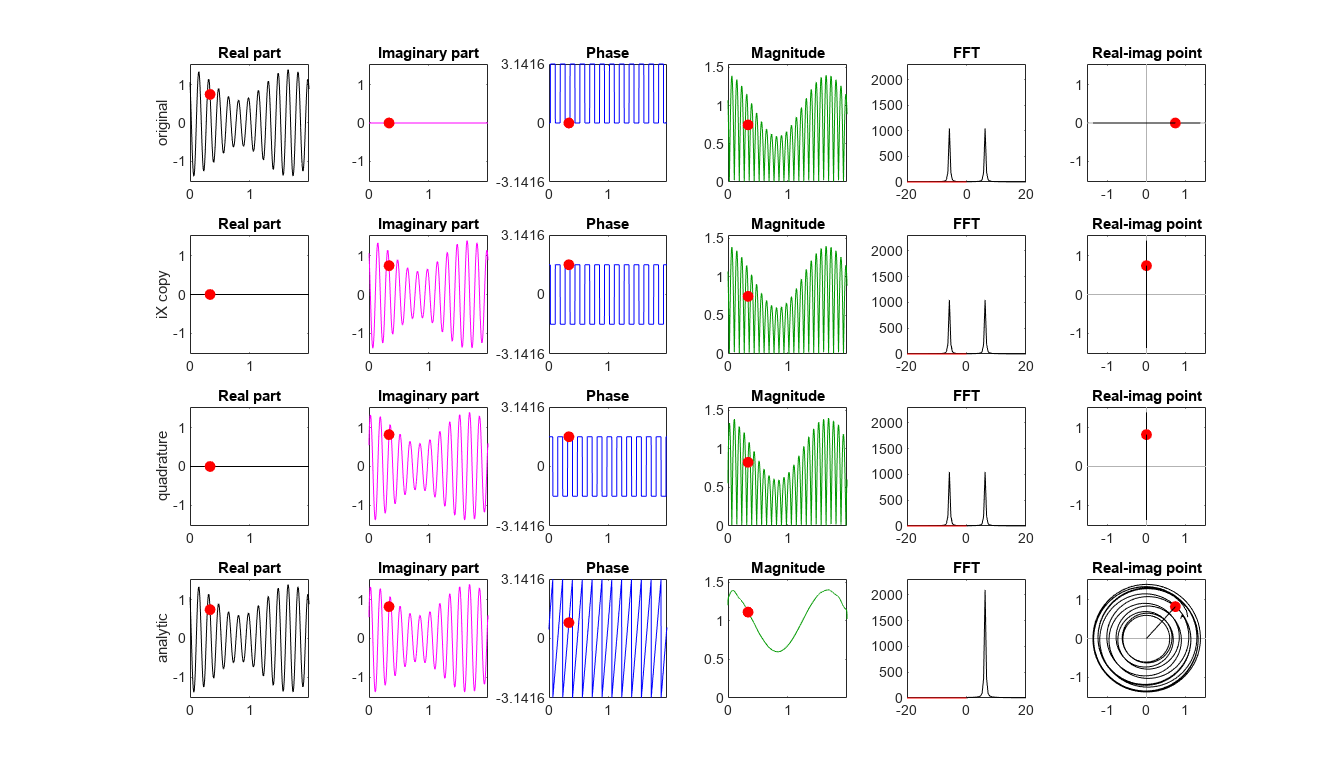

srate = 1000;
time = 0:1/srate:2-1/srate;

freq = 6;
amp = 1 + .4*cos(2*pi*.6*time);
eeg = amp .* cos(2*pi*freq*time + .7);

n = length(eeg);
f = fft(eeg);
fcopy = 1i*f;

fpos = 2:floor(n/2);
fneg = ceil(n/2)+2-mod(n,2):n;

fquad = zeros(size(f));
fquad(fpos) = -1i*fcopy(fpos);
fquad(fneg) = 1i*fcopy(fneg);

fmod = f + fquad;

z = zeros(4,n);

z(1,:) = ifft(f);
z(2,:) = ifft(fcopy);
z(3,:) = ifft(fquad);
z(4,:) = ifft(fmod);

fz = zeros(4,n);

fz(1,:) = f;
fz(2,:) = fcopy;
fz(3,:) = fquad;
fz(4,:) = fmod;

hz = linspace(0,srate,n);
hz = hz - srate/2;

ti = 338;

yl = max(abs([real(z(:)); imag(z(:))]))*1.1;
ml = max(abs(z(:)))*1.1;
fl = max(abs(fz(:)))*1.1;

rnames = {'original','iX copy','quadrature','analytic'};

figure(Position=[100,100,1700,1000])


for ri = 1:4
    
    subplot(4,6,(ri-1)*6+1)
    plot(time,real(z(ri,:)),'k')
    hold on
    plot(time(ti),real(z(ri,ti)),'ro','markerfacecolor','r')
    set(gca,'xlim',[time(1) time(end)],'ylim',[-yl yl])
    title('Real part')
    ylabel(rnames{ri})
    
    subplot(4,6,(ri-1)*6+2)
    plot(time,imag(z(ri,:)),'m')
    hold on
    plot(time(ti),imag(z(ri,ti)),'ro','markerfacecolor','r')
    set(gca,'xlim',[time(1) time(end)],'ylim',[-yl yl])
    title('Imaginary part')
    
    subplot(4,6,(ri-1)*6+3)
    plot(time,angle(z(ri,:)),'b')
    hold on
    plot(time(ti),angle(z(ri,ti)),'ro','markerfacecolor','r')
    set(gca,'xlim',[time(1) time(end)],'ylim',[-pi pi],'ytick',[-pi 0 pi])
    title('Phase')
    
    subplot(4,6,(ri-1)*6+4)
    plot(time,abs(z(ri,:)),'color',[0 .6 0])
    hold on
    plot(time(ti),abs(z(ri,ti)),'ro','markerfacecolor','r')
    set(gca,'xlim',[time(1) time(end)],'ylim',[0 ml])
    title('Magnitude')
    
    subplot(4,6,(ri-1)*6+5)
    fzt = fftshift(fz(ri,:));
    plot(hz,abs(fzt),'k')
    hold on
    plot(hz(fpos)-srate/2,abs(fzt(fpos)),'b')
    plot(hz(fneg)-srate/2,abs(fzt(fneg)),'r')
    set(gca,'xlim',[-20 20],'ylim',[0 fl])
    title('FFT')
    
    subplot(4,6,(ri-1)*6+6)
    plot([-yl yl],[0 0],'color',[.7 .7 .7])
    hold on
    plot([0 0],[-yl yl],'color',[.7 .7 .7])
    plot(real(z(ri,:)),imag(z(ri,:)),'k')
    plot(real(z(ri,ti)),imag(z(ri,ti)),'ro','markerfacecolor','r')
    plot([0 real(z(ri,ti))],[0 imag(z(ri,ti))],'k')
    set(gca,'xlim',[-yl yl],'ylim',[-yl yl])
    title('Real-imag point')
    
end

**Figure 14.1**

*Illustration of the Hilbert transform for a nonstationary oscillatory signal. The procedure operates in the Fourier domain by preserving the original real-valued signal, creating a phase-quadrature component, and combining them to produce the analytic signal.*

The Hilbert transform does not affect the real part of the signal. This can be shown by plotting a cosine wave and the real component of that cosine wave after Hilbert transform.

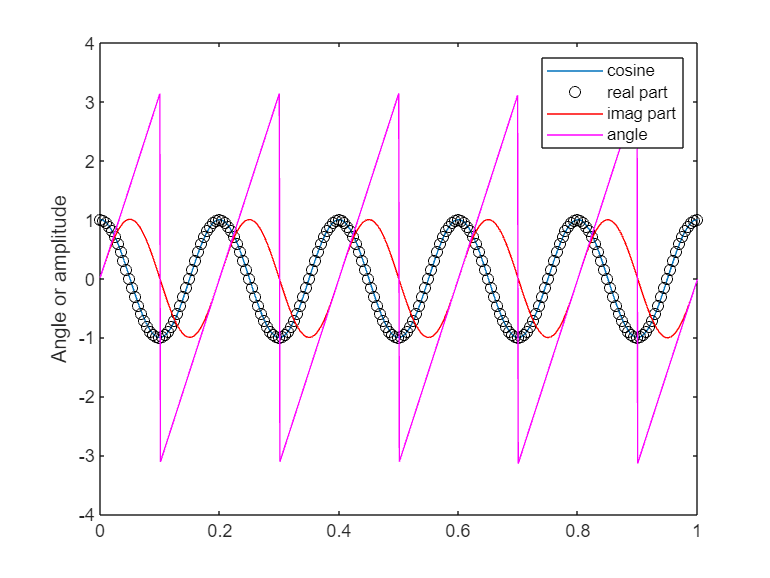

time   = 0:.001:1;
cosine = cos(2*pi*5*time);

figure
plot(time,cosine)
hold on
plot(time(1:5:end),real(hilbert(cosine(1:5:end))),'ko')
plot(time,imag(hilbert(cosine)),'r')
plot(time,angle(hilbert(cosine)),'m')

ylabel('Angle or amplitude')
legend({'cosine';'real part';'imag part';'angle'})

**Figure 14.2**

*The Hilbert transform is used to extract complex information from a real-valued signal. Here, a cosine wave was created (solid gray line), and its Hilbert transform was taken. The real part of the result of the Hilbert transform is the original signal, while the imaginary part is a sine wave (which is what happens when a cosine is phase-shifted 90 °).*

Important! The Matlab function `hilbert` will accept a matrix as input and compute the FFT over the first dimension. This is useful to apply the Hilbert transform to many trials or many electrodes in one command.

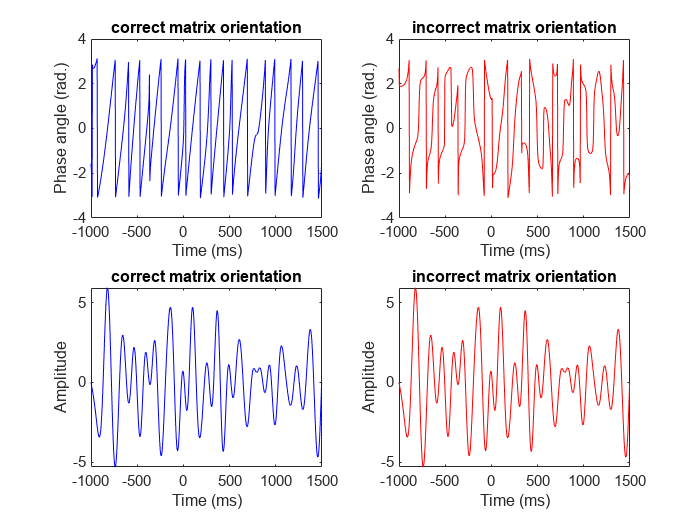

load sampleEEGdata

nyquist = EEG.srate/2;
lower_filter_bound = 4;
upper_filter_bound = 10;
transition_width   = 0.2;

filter_order       = round(3*(EEG.srate/lower_filter_bound));

ffrequencies  = [ 0 (1-transition_width)*lower_filter_bound lower_filter_bound upper_filter_bound (1+transition_width)*upper_filter_bound nyquist ]/nyquist;
idealresponse = [ 0 0 1 1 0 0 ];
filterweights = firls(filter_order,ffrequencies,idealresponse);

filtered_data = zeros(EEG.nbchan,EEG.pnts);
for chani=1:EEG.nbchan
    filtered_data(chani,:) = filtfilt(filterweights,1,double(EEG.data(chani,:,1)));
end

hilbert_oops = hilbert(filtered_data);
hilbert_yes  = hilbert(filtered_data')';

figure
subplot(221)
plot(EEG.times,angle(hilbert_yes(1,:)'),'b');
title('correct matrix orientation')
xlabel('Time (ms)'), ylabel('Phase angle (rad.)')
set(gca,'xlim',[-1000 1500])

subplot(222)
plot(EEG.times,angle(hilbert_oops(1,:)),'r');
title('incorrect matrix orientation')
xlabel('Time (ms)'), ylabel('Phase angle (rad.)')
set(gca,'xlim',[-1000 1500])

subplot(223)
plot(EEG.times,real(hilbert_yes(1,:)),'b');
title('correct matrix orientation')
xlabel('Time (ms)'), ylabel('Amplitude')
set(gca,'xlim',[-1000 1500])

subplot(224)
plot(EEG.times,real(hilbert_oops(1,:)),'r');
title('incorrect matrix orientation')
xlabel('Time (ms)'), ylabel('Amplitude')
set(gca,'xlim',[-1000 1500])

**Figure 14.3**

*Applying the Matlab *`hilbert`* function to matrix data can produce incorrect results if the input data matrix is incorrectly oriented. This is easily identified by plotting the angle of the result of the Hilbert transform (top row). the Hilbert transform does not change the real component (bottom row).*

## 14.2 Filtering Data before Applying the Hilbert Transform

Bandpass filtering is not necessary; you can simply apply the Hilbert transform to the broadband data. However, the resulting analytic signal may be difficult to interpret because all frequencies present in the data will contribute to the result, and frequencies with more power (generally lower frequencies because of power-law scaling) will contribute more compared to frequencies with less power (generally higher frequencies). Thus, you should filter the data into separate frequency bands before applying the Hilbert transform. This way, results can be interpreted in a frequency-band-specific manner.

This leads to the main advantage of the filter-Hilbert method over complex wavelet convolution: you have more control over the characteristics of the filter, compared to the amount of control you have over the characteristics of Morlet wavelets. In fact, you have no control over the shape of the Morlet wavelet; it is always Gaussian shaped in the frequency domain. A bandpass filter, on the other hand, can be Gaussian or plateau shaped. 

## 14.3 Finite versus Infinite Impulse Response Filters

Based on how a filter responds to an impulse — a single input, filters can be classified as FIR or IIR:

- **FIR (finite impulse response):** have a response that ends at some point (that is, its response is finite)

- **IIR (infinite impulse response):** have a response that never ends (its response is infinite)

For most situations when using the filter-Hilbert method for time-frequency decomposition of EEG data, FIR filters are preferred over IIR filters. FIR filters are more stable and less likely to introduce nonlinear phase distortions. Although the computational cost is a bit higher compared to IIR filters because of FIR’s increased filter order, in practice this is not a major limitation for modern computers.

## 14.4 Bandpass, Band-Stop, High-Pass, Low-Pass

There are four ways of using filters to highlight some frequencies of the data while attenuating other frequencies: 

- **Bandpass filters:** keep activity between the specified frequencies

- **Band-stop filters:** remove activity between the specified frequencies

- **High-pass filters:** retain high frequencies while attenuating low frequencies

- **Low-pass filters:** retain low frequencies while attenuating high frequencies

For time-frequency decomposition, bandpass filters are the most useful type of filters. Morlet wavelets, as already mentioned in earlier chapters and demonstrated again in this chapter, are bandpass filters.

## 14.5 Constructing a Filter

Bandpass filtering operates on the same convolutional principles as wavelet transforms: a kernel is constructed based on ideal frequency characteristics that you define, and when the kernel is convolved with EEG data, the requested frequencies are preserved while the undesired frequencies are attenuated. 

The power spectrum of a Morlet wavelet is Gaussian shaped. In contrast, the power spectrum of an FIR filter can be plateau shaped. In practice, you can have the FIR filter take any shape you want in the frequency domain, although plateau-shaped filters are recommended. This is why bandpass filtering can provide extra frequency specificity compared to wavelets, and this is why wavelet convolution will generally produce timefrequency plots that appear a bit smoother over the frequency axis compared to timefrequency plots produced by the filter-Hilbert method.

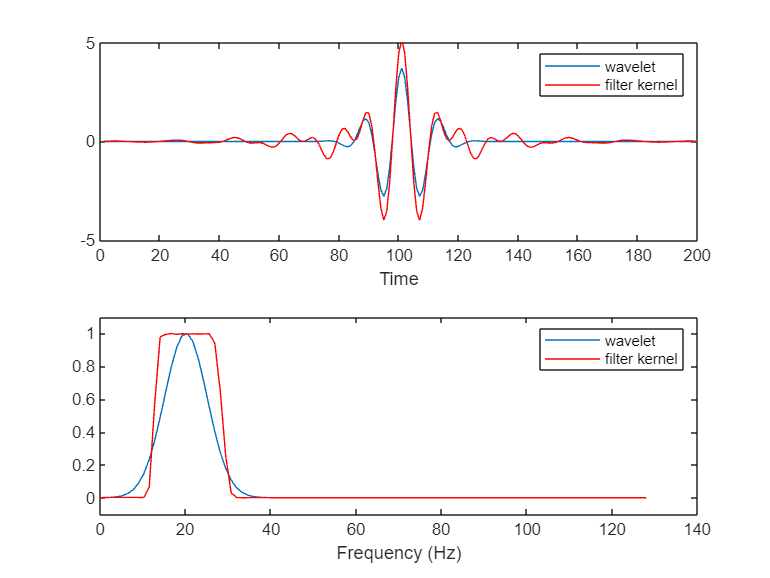

center_freq = 20;
filter_frequency_spread  = 6;
wavelet_frequency_spread = 4;

time = -1000/EEG.srate/10:1/EEG.srate:1000/EEG.srate/10;
wavelet = zscore(exp(2*1i*pi*center_freq.*time) .* exp(-time.^2./(2*(wavelet_frequency_spread/(2*pi*center_freq))^2)));
fft_wavelet = abs(fft(wavelet));
fft_wavelet = fft_wavelet./max(fft_wavelet);
hz_wavelet  = linspace(0,nyquist,length(time)/2+1);

transition_width = 0.2;
ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread) (center_freq-filter_frequency_spread) (center_freq+filter_frequency_spread) (1+transition_width)*(center_freq+filter_frequency_spread) nyquist ]/nyquist;
idealresponse  = [ 0 0 1 1 0 0 ];
filterweights  = zscore(firls(200,ffrequencies,idealresponse));
fft_filtkern  = abs(fft(filterweights));
fft_filtkern  = fft_filtkern./max(fft_filtkern);

filterweights1 = zscore(fir1(200,[center_freq-filter_frequency_spread center_freq+filter_frequency_spread]./nyquist));
fft_filtkern1 = abs(fft(filterweights1));
fft_filtkern1 = fft_filtkern1./max(fft_filtkern1);

hz_filtkern   = linspace(0,nyquist,101);

figure

subplot(211)
plot(real(wavelet))
hold on
plot(filterweights,'r')
legend({'wavelet';'filter kernel'})
set(gca,'xlim',[0 200],'ylim',[-5 5])
xlabel('Time')


subplot(212)
plot(hz_wavelet,fft_wavelet(1:ceil(length(fft_wavelet)/2)))
hold on
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'r')
legend({'wavelet';'filter kernel'})
set(gca,'ylim',[-.1 1.1])
xlabel('Frequency (Hz)')

**Figure 14.4**

*Comparison of the time-domain and frequency-domain representations of a Morlet wavelet and an FIR filter kernel. Both the wavelet and the filter kernel were designed to isolate 20-Hz activity. Data were amplitude-normalized to facilitate visual comparison. It also illustrates why it is informative to refer to the “peak” frequency of a wavelet and the “center” frequency of a bandpass filter.*

Broadly speaking, the way to create a filter kernel is by specifying the ideal filter shape and the frequencies that define that shape. Frequencies are specified as a fraction of the Nyquist frequency. There are several functions in Matlab to construct filter kernels, most of which are contained in the signal-processing toolbox. 

The two functions that are discussed here are: 

- `firls:` create finite-impulse response filters via least squares

- `fir1:` create finite-impulse response filters via a windowed linear phase filter with tight transition zones

Other Matlab functions for creating filter kernels include: 

- `fir2:` frequency-sampling-based filter construction

- `firrcos:` raised cosine-shaped filter

- `gaussfir:` Gaussian-shaped filter

- `firpm:` Parks-McClellan

You can also create your own filter kernels, but this is not recommended unless you are knowledgeable about the mechanics of proper filter kernel construction.

There are three inputs to the Matlab function `firls` (several of the other filter construction functions take the same inputs, although `fir1` takes only the first two of the following inputs):

- **Order parameter:** defines the length of the filter kernel (the length of kernel is the order plus one). The filter order determines the precision of the filter’s frequency response. The lower bound of the filter kernel is one full cycle of the target frequency (In practice, it is good to have somewhere between two and five times the lower frequency bound). The order may change as a function of the center frequency of the bandpass filter. In theory, the filter order must be an even number to exclude a filter representation for the Nyquist frequency.

- **Vector of frequencies:** defines the shape of the response. For a bandpass `firls` filter, you can use six numbers: the zero frequency, the frequency of the start of the lower transition zone, the lower bound of the bandpass, the upper bound of the bandpass, the frequency of the end of the upper transition zone, and finally the Nyquist frequency. These numbers are scaled such that the Nyquist frequency is 1.0. For the function `fir1` , you enter only two numbers, the lower and upper bounds of the filter, because transition zones are set to zero.

- **Ideal filter response amplitude:** This is a vector comprising as many numbers as the second input and contains zeros for the frequencies you want to attenuate and ones for the frequencies you want to keep. For a bandpass filter, you can use [0 0 1 1 0 0], where the ones correspond to the lower and upper frequency bounds of the bandpass plateau, the first and last zero corresponds to the DC and Nyquist frequencies, and the second and fifth zeroes correspond to the frequency bounds of the transition zones. You can also use numbers between zero and one if you want to suppress but in practice it is best to keep the filter shape simple.

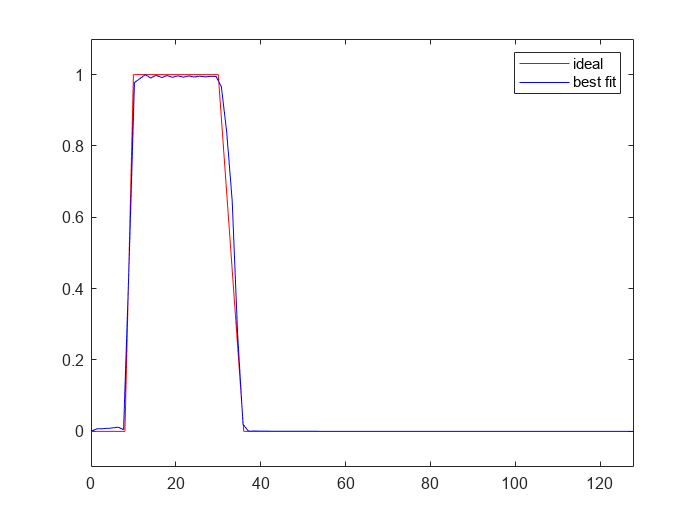

center_freq = 20;
filter_frequency_spread_wide = 10;

ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_wide) (center_freq-filter_frequency_spread_wide) (center_freq+filter_frequency_spread_wide) (1+transition_width)*(center_freq+filter_frequency_spread_wide) nyquist ]/nyquist;
idealresponse  = [ 0 0 1 1 0 0 ];
filterweightsW = zscore(firls(200,ffrequencies,idealresponse));

figure
plot(ffrequencies*nyquist,idealresponse,'r')
hold on

fft_filtkern  = abs(fft(filterweightsW));
fft_filtkern  = fft_filtkern./max(fft_filtkern);
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'b')

set(gca,'ylim',[-.1 1.1],'xlim',[0 nyquist])
legend({'ideal';'best fit'})

**Figure 14.5**

*This figure illustrates how to define an ideal frequency response for a plateau shaped FIR filter (see dotted line), and the numbers show which frequency points will be used as the input to firls . The units are scaled by the Nyquist frequency (thus, the first input is 0 and the last input, which is the Nyquist frequency, is 1). If you use the fir1 function, only the frequencies corresponding to (3) and (4) are used as inputs. The slopes from (2) to (3), and from (4) to (5), are called the transition zones. The actual frequency response of the filter kernel (solid line) is a least-squares approximation of the ideal response.*

You are not limited to inputs of six numbers. You can use as many numbers as you want to maximize the control over the precise shape of the filter. In theory, you can make more complicated filters, for example those containing two spectral peaks at different frequencies. However, complicated filter shapes are difficult to design and may introduce artifacts in the time-domain data. In the case of multipeak filters, those artifacts may be difficult to detect.

The frequency width of the bandpass filter (that is, the length of the plateau in the frequency representation of the filter kernel) and the transition zones define the trade-off between temporal precision and frequency precision. As the plateau becomes narrower, the frequency precision increases, but this decreases the temporal precision because narrow frequency filters require longer kernels to resolve.

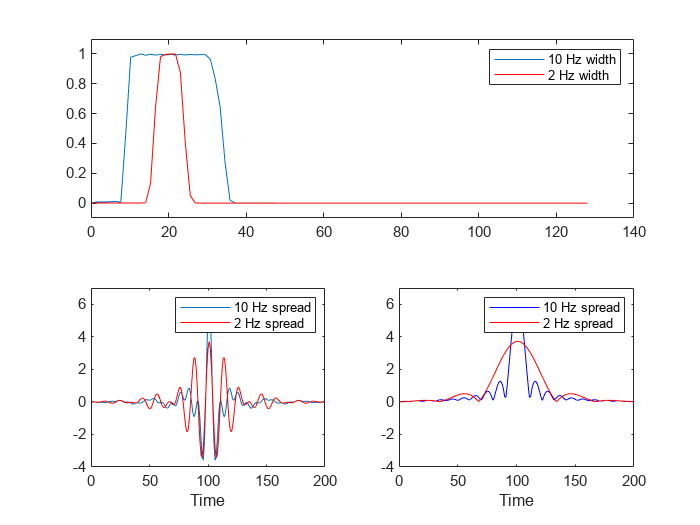

center_freq = 20;
filter_frequency_spread_wide = 10;
filter_frequency_spread_naro =  2;


ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_wide) (center_freq-filter_frequency_spread_wide) (center_freq+filter_frequency_spread_wide) (1+transition_width)*(center_freq+filter_frequency_spread_wide) nyquist ]/nyquist;
idealresponse  = [ 0 0 1 1 0 0 ];
filterweightsW = zscore(firls(200,ffrequencies,idealresponse));

ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_naro) (center_freq-filter_frequency_spread_naro) (center_freq+filter_frequency_spread_naro) (1+transition_width)*(center_freq+filter_frequency_spread_naro) nyquist ]/nyquist;
filterweightsN = zscore(firls(200,ffrequencies,idealresponse));


figure
subplot(211)
fft_filtkern  = abs(fft(filterweightsW));
fft_filtkern  = fft_filtkern./max(fft_filtkern);
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)))

hold on
fft_filtkern  = abs(fft(filterweightsN));
fft_filtkern  = fft_filtkern./max(fft_filtkern);
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'r')
set(gca,'ylim',[-.1 1.1])
legend({'10 Hz width';'2 Hz width'})

subplot(223)
plot(filterweightsW)
hold on
plot(filterweightsN,'r')
set(gca,'xlim',[0 200],'ylim',[-4 7])
legend({'10 Hz spread';'2 Hz spread'})
xlabel('Time')

subplot(224)
plot(abs(hilbert(filterweightsW)),'b')
hold on
plot(abs(hilbert(filterweightsN)),'r')
set(gca,'xlim',[0 200],'ylim',[-4 7])
legend({'10 Hz spread';'2 Hz spread'})
xlabel('Time')

**Figure 14.6**

*Illustration of how the width of the filter controls the time-frequency precision trade-off in bandpass filtering.*

Filter ripple artifacts can appear as oscillations in the filtered signal and may arise from sharp edges in either the time domain or the frequency domain:

- Sharp edges in the time domain can produce artifacts in the frequency domain 

- Sharp edges in the frequency domain can produce artifacts in the time domain

Sharp edges in the frequency domain can be avoided by using transition zones. If you use `firls`, the transition zones should be between 10% and 25% of the lower and upper frequency bounds. 

There is a trade-off for the width of the transition zones: 

- Sharper transition zones give a better frequency response but increase the risk of introducing time-domain ringing artifacts

- Gentler transition zones decrease the risk of time-domain ringing artifacts but also have less frequency specificity

If you plan on using a transition zone of less than 10%, 

- Smooth the filter kernel using a Hann or Hamming 

- Use the function `fir1`

- Increase the order of the filter

The main difference between the filter kernels created by `firls` and `fir1` is the transition zone: 

- `firls` is a general function for filter kernel construction that allows you to define your own transition zones

- `fir1` automatically sets the transition zones to zero and then smoothes the resulting filter kernel to minimize ringing artifacts. This smoothing effectively creates a nonzero transition zone

In fact, by using `firls` with transition zones of zero and then smoothing the resulting filter kernel with a Hamming window, you can nearly perfectly reconstruct the filter kernel created by `fir1. `Thus, the added flexibility of `firls` can lead to a better or worse filter design, depending on the input parameters you specify and the goal of the filtering. If you want to make the filter as narrow-band as possible, it is best to use `fir1.` If you are concerned about potential ringing artifacts in the time-domain data, or if you are using fairly wide pass bands, `firls` might be advantageous because you can specify gentle transition zones. If you are unsure which filter kernel to use, you can plot the kernel and its frequency representation, carefully inspect some sample data before and after applying different filters, and make an informed decision.

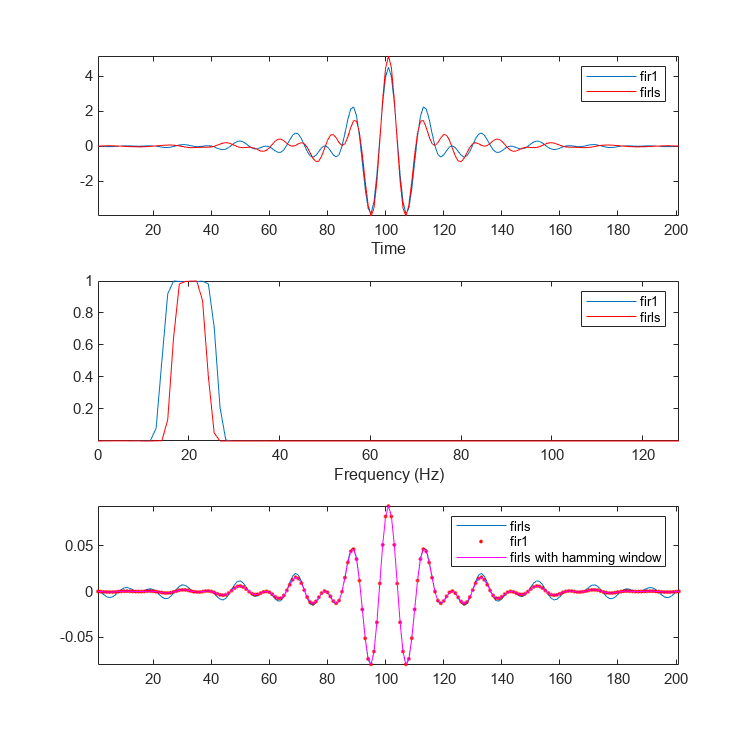

figure(Position=[100,100,600,600])

subplot(311)
plot(filterweights1)
hold on
plot(filterweights,'r')
legend({'fir1';'firls'})
set(gca,'xlim',[0 200])
xlabel('Time')
axis tight

subplot(312)
plot(hz_filtkern,fft_filtkern1(1:ceil(length(fft_filtkern1)/2)))
hold on
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'r')
legend({'fir1';'firls'})
set(gca,'ylim',[-.1 1.1])
xlabel('Frequency (Hz)')
axis tight

freqL = center_freq-filter_frequency_spread;
freqU = center_freq+filter_frequency_spread;

ffrequencies   = [ 0 freqL freqL freqU freqU nyquist ]/nyquist;
filterweights  = firls(200,ffrequencies,idealresponse);
filterweights1 = fir1(200,[freqL freqU]./nyquist);

subplot(313)
plot(filterweights)
hold on
plot(filterweights1,'r.')
plot(filterweights.*hamming(length(filterweights))','m')
legend({'firls';'fir1';'firls with hamming window'})
axis tight

**Figure 14.7**

*Comparisons of the time and frequency representations of FIR filter kernels created through Matlab functions fir1 and firls.*

## 14.6 Check Your Filters

Check your filters carefully before applying them. You might have a poorly constructed filter without knowing it, and this may have negative consequences for your results. A poorly constructed filter means that there is a poor match between the frequency representation of the filter kernel and the ideal filter that you specified. In general, the fit of the actual filter to the ideal filter is a function of the center frequency, the pass-band width, the transition zones, and the filter order. The “goodness” of a filter can be quantified as the similarity between the actual frequency characteristics of the filter and the frequency characteristics of the ideal filter that you specified. Formally, this can be measured as a sum of squared errors.

### 
$$\textrm{sse}=\sum_{i=1}^n {\left({\textrm{ideal}}_i -{\textrm{actual}}_i \right)}^2$$


- $\textrm{sse}$ is the sum of squared errors

- $n$ is the number of frequencies that were specified in the ideal filte

- $\textrm{ideal}$ is the power spectra of the ideal filter

- $\textrm{actual}$ is the power spectra of the filter kernel

Note that the ideal filter has as many as there are points in the third input to the `firls` function, whereas the actual filter power spectrum has as many numbers as there are points in the filter kernel (that is, the order parameter plus one). Thus, you will have to match the frequency points appropriately.

The $\textrm{sse}$ should be very close to zero, and you should not use any filter that has an $\textrm{sse}$ above one.

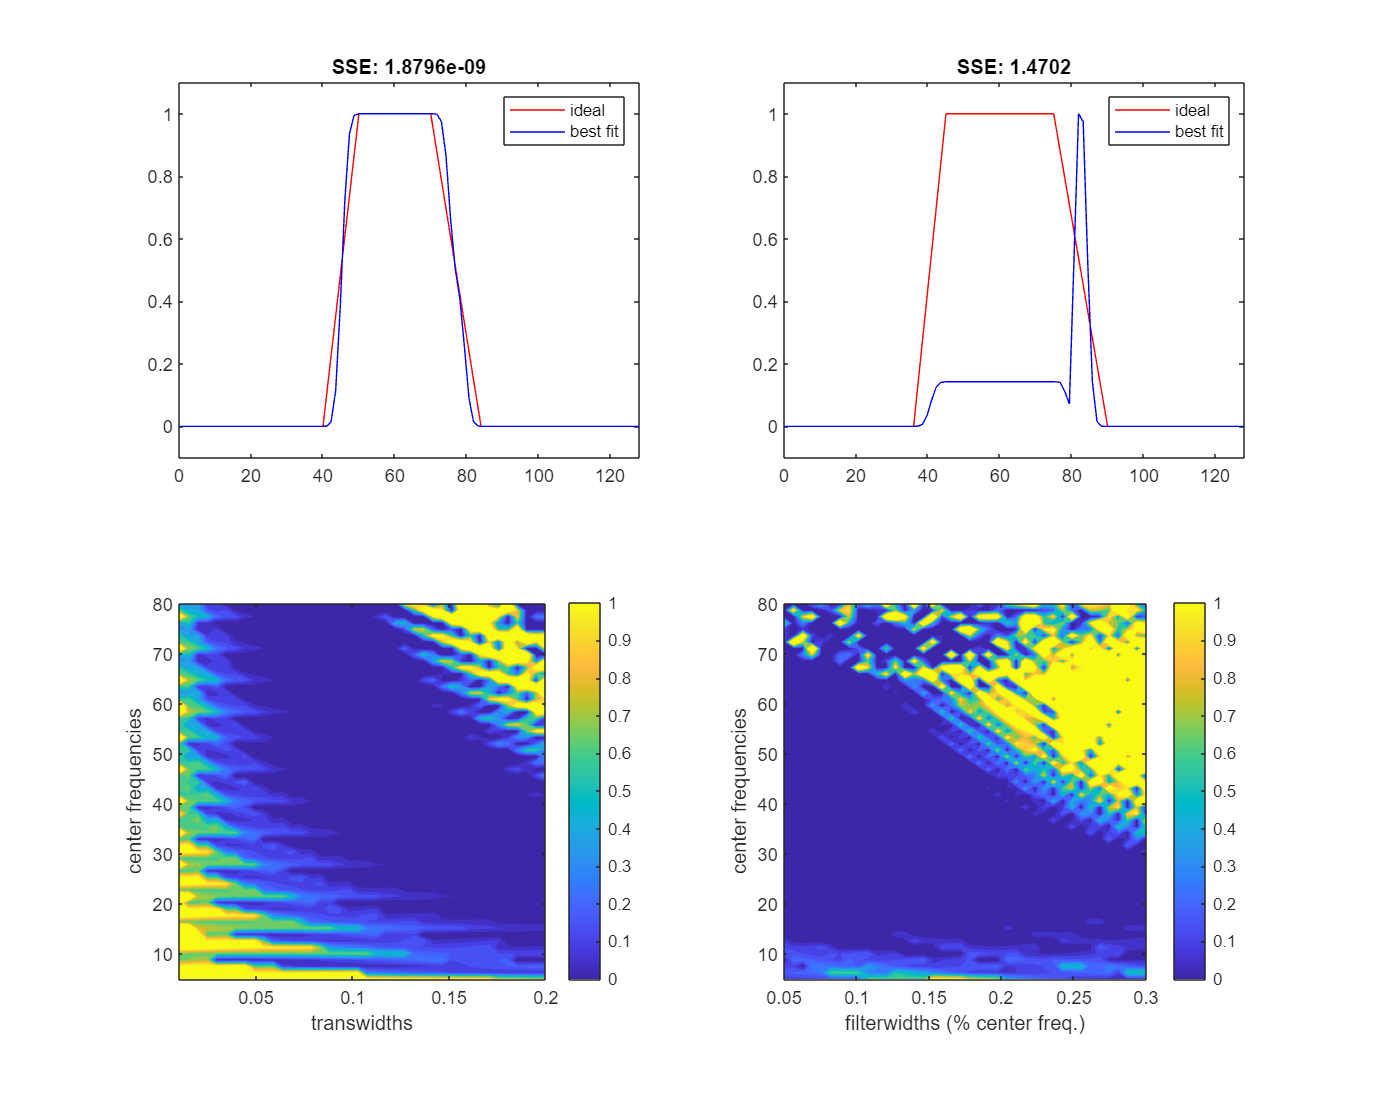

warning('off')

center_freq = 60;
filter_frequency_spread_wide = 10;

ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_wide) (center_freq-filter_frequency_spread_wide) (center_freq+filter_frequency_spread_wide) (1+transition_width)*(center_freq+filter_frequency_spread_wide) nyquist ]/nyquist;
idealresponse  = [ 0 0 1 1 0 0 ];
filterweightsW = zscore(firls(200,ffrequencies,idealresponse));

figure(Position=[100,100,1000,800])

subplot(221)
plot(ffrequencies*nyquist,idealresponse,'r')
hold on

fft_filtkern  = abs(fft(filterweightsW));
fft_filtkern  = fft_filtkern./max(fft_filtkern);
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'b')

set(gca,'ylim',[-.1 1.1],'xlim',[0 nyquist])
legend({'ideal';'best fit'})

freqsidx = dsearchn(hz_filtkern',ffrequencies'*nyquist);
title([ 'SSE: ' num2str(sum( (idealresponse-fft_filtkern(freqsidx)).^2 )) ])

center_freq = 60;
filter_frequency_spread_wide = 15;

ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_wide) (center_freq-filter_frequency_spread_wide) (center_freq+filter_frequency_spread_wide) (1+transition_width)*(center_freq+filter_frequency_spread_wide) nyquist ]/nyquist;
idealresponse  = [ 0 0 1 1 0 0 ];
filterweightsW = zscore(firls(200,ffrequencies,idealresponse));

subplot(222)
plot(ffrequencies*nyquist,idealresponse,'r')
hold on

fft_filtkern  = abs(fft(filterweightsW));
fft_filtkern  = fft_filtkern./max(fft_filtkern); % normalized to 1.0 for visual comparison ease
plot(hz_filtkern,fft_filtkern(1:ceil(length(fft_filtkern)/2)),'b')

set(gca,'ylim',[-.1 1.1],'xlim',[0 nyquist])
legend({'ideal';'best fit'})

freqsidx = dsearchn(hz_filtkern',ffrequencies'*nyquist);
title([ 'SSE: ' num2str(sum( (idealresponse-fft_filtkern(freqsidx)).^2 )) ])

centerfreqs  = linspace(5,80,60);
transwidths  = linspace(0.01,0.2,40);
filterwidths = linspace(0.05,0.3,40);


sse = zeros(length(centerfreqs),length(transwidths));
for centfreqi = 1:length(centerfreqs)
    
    center_freq = centerfreqs(centfreqi);
    
    for transwidi = 1:length(transwidths)
        
        filter_frequency_spread_wide = center_freq*.2;
        transition_width = transwidths(transwidi);
        
        ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_wide) (center_freq-filter_frequency_spread_wide) (center_freq+filter_frequency_spread_wide) (1+transition_width)*(center_freq+filter_frequency_spread_wide) nyquist ]/nyquist;
        filterweightsW = zscore(firls(200,ffrequencies,idealresponse));
        
        fft_filtkern   = abs(fft(filterweightsW));
        fft_filtkern   = fft_filtkern./max(fft_filtkern);
        freqsidx = dsearchn(hz_filtkern',ffrequencies'*nyquist);
        
        sse(centfreqi,transwidi) = sum( (idealresponse-fft_filtkern(freqsidx)).^2 );
    end
end

subplot(223)
contourf(transwidths,centerfreqs,sse,40,'linecolor','none')
xlabel('transwidths'), ylabel('center frequencies')
set(gca,'clim',[0 1]), colorbar


sse = zeros(length(centerfreqs),length(transwidths));
for centfreqi = 1:length(centerfreqs)
    
    center_freq = centerfreqs(centfreqi);
    
    for transwidi = 1:length(transwidths)
        
        filter_frequency_spread_wide = center_freq*filterwidths(transwidi);
        transition_width = .2;
        
        ffrequencies   = [ 0 (1-transition_width)*(center_freq-filter_frequency_spread_wide) (center_freq-filter_frequency_spread_wide) (center_freq+filter_frequency_spread_wide) (1+transition_width)*(center_freq+filter_frequency_spread_wide) nyquist ]/nyquist;
        filterweightsW = zscore(firls(200,ffrequencies,idealresponse));
        
        fft_filtkern  = abs(fft(filterweightsW));
        fft_filtkern  = fft_filtkern./max(fft_filtkern); % normalized to 1.0 for visual comparison ease
        freqsidx = dsearchn(hz_filtkern',ffrequencies'*nyquist);
        
        sse(centfreqi,transwidi) = sum( (idealresponse-fft_filtkern(freqsidx)).^2 );
    end
end

warning('on')

subplot(224)
contourf(filterwidths,centerfreqs,sse,40,'linecolor','none')
xlabel('filterwidths (% center freq.)'), ylabel('center frequencies')
set(gca,'clim',[0 1]), colorbar

**Figure 14.8**

*Examples of filter parameters that created poorly constructed filters. *$\textrm{SSE}$* is the sum of squared errors between the ideal response and the actual frequency response of the filter. In all cases the filter order was set to 200, and the Nyquist frequency was 128 Hz. Examples of good and bad filters are shown in top two panels. In this case the only difference between the ideal filters used to create these two filter kernels was the passband width — 10 Hz for the good filter and 15 Hz for the bad filter. Bottom left panel shows *$\textrm{SSE}$* as a function of the center frequency and pass-band width, with the transition zone held constant at 20%; and bottom right panel shows *$\textrm{SSE}$* as a function of the center frequency and the transition width, with the pass-band width held constant at 20% of the center frequency. *

For some extremely poorly designed filters, Matlab will issue a warning. However, other poorly designed filters will not be recognized by Matlab as requiring a warning.

## 14.7 Applying the Filter to Data

The function `firls` (and most other filter construction functions including `fir1`) returns a vector of length $N+1$, where $N$ is the order. This is the filter kernel. The next step in filtering EEG data is to apply that filter kernel to the data. This can be done using the Matlab function `filtfilt`. The inputs to the function `filtfilt` are the filter kernel, a scalar or vector of weighting coefficients, and the data time series. The filter kernel is the output of `firls` , and the weighting coefficient can be set to 1.0 unless you would like to apply a weighting to the filter kernel, which is not typically necessary for time-frequency decomposition of EEG data. The output of `filtfilt` is the filtered data.

How does filtering work? It works in a conceptually similar way to wavelet convolution.

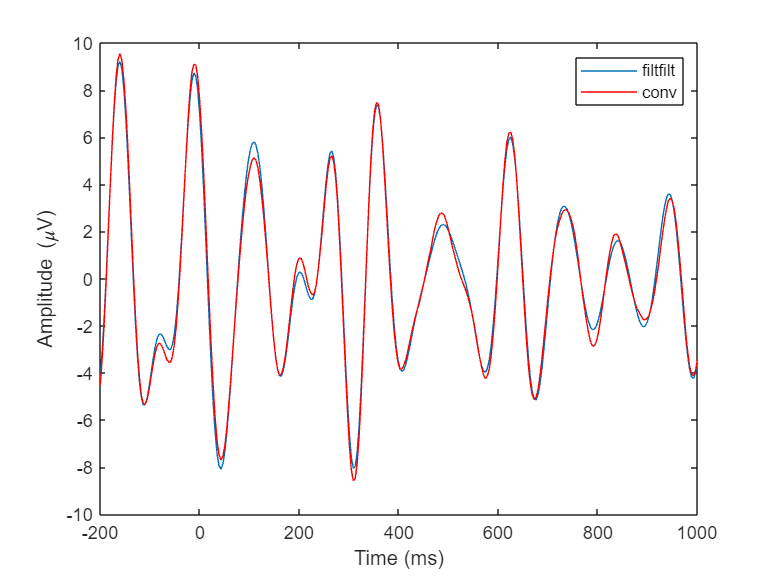

center_freq   = 10;
freqspread    = 4;
transwid      = .10;
ffrequencies  = [ 0 (1-transwid)*(center_freq-freqspread) (center_freq-freqspread) (center_freq+freqspread) (1+transwid)*(center_freq+freqspread) nyquist ]/nyquist;

data2filter   = squeeze(double(EEG.data(47,:,1)));
filterweights = firls(200,ffrequencies,idealresponse);

filter_result = filtfilt(filterweights,1,data2filter);
convol_result = conv(data2filter,filterweights,'same');

figure
plot(EEG.times,filter_result)
hold on
plot(EEG.times,convol_result,'r')
set(gca,'xlim',[-200 1000])
xlabel('Time (ms)'), ylabel('Amplitude (\muV)');
legend({'filtfilt';'conv'})

**Figure 14.9**

*Convolution and zero-phase-shift filtering using the same filter kernel produce very similar results. A filter kernel was created using the Matlab function *`firls`*, and then this filter kernel was used to bandpass- filter EEG data using the Matlab function *`filtfilt`* (a zero-phase-shift filter; black line) and using convolution (gray line).*

The Matlab function `filtfilt` calls a function called `filter`. The function `filter `introduces a phase delay in the filtered signal because it is a causal filter, meaning that the filtered signal at any point in time is based only on previous values, not on future values. These phase delays can be reversed by refiltering the already-filtered data after reversing the filtered data in time. Thus, the phase delay that was introduced in the forward-going filter is reversed, and the final result contains no phase delays. Wavelet convolution does not introduce phase delays because convolution is noncausal, meaning that the filtered signal at each time point is based both on previous and on future values of the signal. Thus, convolution does not need to be repeated with time reversed.

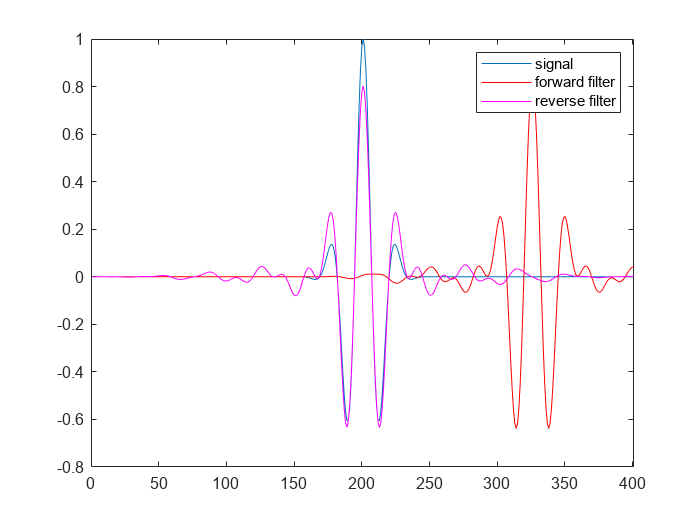

center_freq = 10;
nyquist     = EEG.srate/2;

time    = -2000/EEG.srate/10:1/EEG.srate:2000/EEG.srate/10;
wavelet = cos(2*pi*center_freq.*time) .* exp(-time.^2./(2*(3/(2*pi*center_freq))^2));


freqspread = 4;
transwid   = .10;

ffrequencies  = [ 0 (1-transwid)*(center_freq-freqspread) (center_freq-freqspread) (center_freq+freqspread) (1+transwid)*(center_freq+freqspread) nyquist ]/nyquist;
idealresponse = [ 0 0 1 1 0 0 ];
filterweights = firls(250,ffrequencies,idealresponse);


forward_filt = filter(filterweights,1,wavelet);
reverse_filt = filter(filterweights,1,forward_filt(end:-1:1));
final_filt_result = reverse_filt(end:-1:1);

figure
plot(wavelet)
hold on
plot(forward_filt,'r')
plot(reverse_filt,'m')

set(gca,'xlim',[0 length(wavelet)])
legend({'signal';'forward filter';'reverse filter'})

**Figure 14.10**

*The Matlab function *`filter`* introduces a phase delay, which can be reversed by filtering the filtered data again after being flipped backward in time. The reverse filtered result should then be reversed again to arrive at the original orientation of time (in most cases, time originally goes forward).*

After you have applied the filter to the data, the result is a real-valued signal that contains only those frequencies specified by the frequency response of the filter kernel. The Hilbert transform can then be applied to the bandpass-filtered signal, and the analytic result of the Hilbert transform can be used to extract power and phase information.

## 14.8 Butterworth (IIR) Filter 

Perhaps the most common type of IIR filter used for EEG is the Butterworth filter. Constructing a Butterworth filter is similar to how FIR filters are constructed and produces similar results

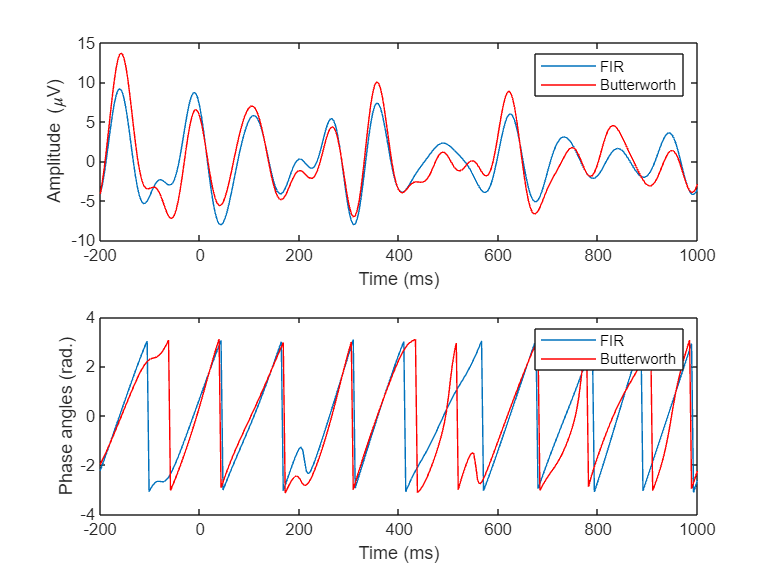

[butterB,butterA] = butter(5,[(center_freq-filter_frequency_spread)/nyquist (center_freq+filter_frequency_spread)/nyquist],'bandpass');
butter_filter     = filtfilt(butterB,butterA,data2filter);

figure
subplot(211)

plot(EEG.times,filter_result)
hold on
plot(EEG.times,butter_filter,'r')
set(gca,'xlim',[-200 1000])
xlabel('Time (ms)'), ylabel('Amplitude (\muV)');
legend({'FIR';'Butterworth'})

subplot(212)
plot(EEG.times,angle(hilbert(filter_result)))
hold on
plot(EEG.times,angle(hilbert(butter_filter)),'r')
set(gca,'xlim',[-200 1000])
xlabel('Time (ms)'), ylabel('Phase angles (rad.)');
legend({'FIR';'Butterworth'})

**Figure 14.11**

*Comparison of results after FIR and IIR (fifth-order Butterworth) filter.*

## 14.9 Filtering Each Trial versus Filtering Concatenated Trials

It is faster to concatenate all trials into one long time series, filter that concatenated time series, and then cut out the separate trials, compared to filtering each trial separately. Not only is it faster, it will also facilitate writing cleaner code, in part because it renders a loop over trials unnecessary.

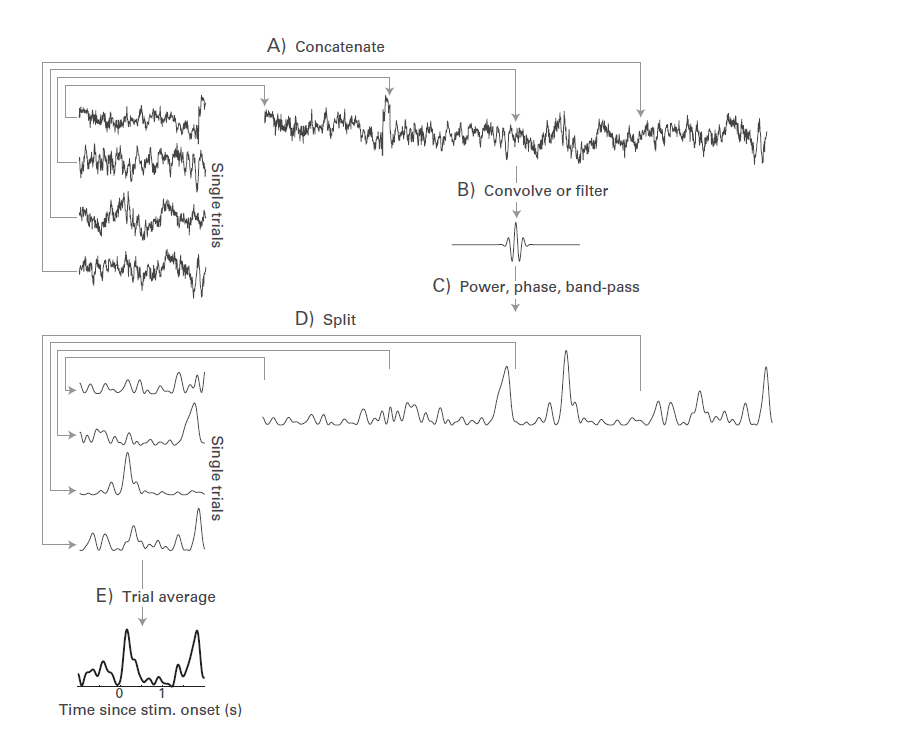

**Figure 14.12**

*Illustration of concatenation procedure to improve performance of time-frequency decomposition.*

The main concern of trial concatenation is edge artifacts. If you use the `filtfilt` function, edge artifacts are less influential when performing single-trial filtering because Matlab’s `filtfilt` function reflects the time series data to minimize edge artifacts. If you have sufficient buffer time at the start and end of trials, edge artifacts will subside by the time period you will analyze. You should avoid filtering concatenated trials if you have short epochs right around the time period in which you want to analyze. in this case, it is also possible to reflect the data on your own and then concatenate the reflected trials.

## 14.10 Multiple Frequencies

As with wavelet convolution, you will probably want to examine activity over many frequency bands. This is done by looping over frequencies and refiltering the raw data into successive frequency bands. You might consider having some frequency overlap in the bands to make smoother and more visually interpretable time-frequency plots. Frequency overlaps of between 25% and 75% are acceptable. Keep in mind that a lot of overlap will increase computation time without providing any new information. Similar to Morlet wavelets, you can create the filters using linear or logarithmic steps. With increasing frequencies, the widths of the filters should also increase.

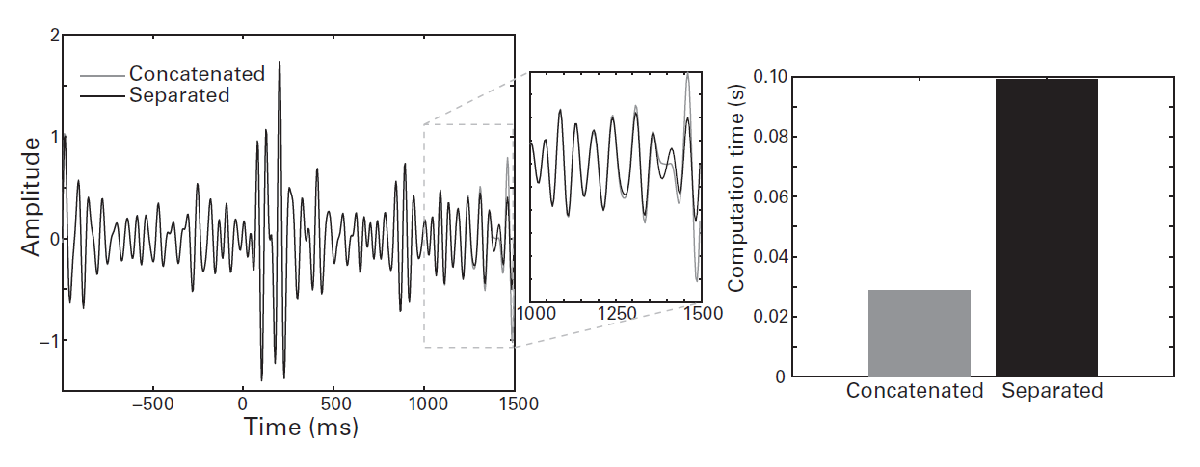

**Figure 14.13**

*Filtering concatenated trials is more elegant and efficient than filtering single trials but produces minor artifacts toward the edges of the data (these are avoided in single-trial filtering due to signal reflection in the Matlab *`filtfilt`* function). The more trials you have, the bigger the increase in speed.*

## 14.11 A World of Filters

Digital signal filtering is a major topic in engineering and science. There are several types of digital temporal filters, and entire books and online resources are devoted to the advantages and disadvantages of different types of filters. This chapter covers slightly more than the minimum you need to know to construct and apply bandpass filters to use in combination with the Hilbert transform for time-frequency analysis of EEG data. Filtering ERPs is a topic of additional debate, and there are several opinions about whether and how filtering affects ERP features such as peak latency and peak-to-peak quantification.

## 14.12 Describing This Analysis in Your Methods Section

If you used the filter-Hilbert method to analyze your data, make sure to include enough detail in the Methods section so that someone else can replicate your analyses. Important pieces of information include: 

- The minimum, maximum, and number of frequency band and whether frequencies increased linearly or logarithmically

- The pass-bandwidths of the frequencies and whether the bandwidths changed as a function of frequency

- The order of the filter and whether the order changed as a function of frequency

- The transition zones of the filter shape

You should also mention which Matlab (or other program) function you used to create the filter kernel (e.g., `fir1` or `firls`). Because poorly constructed filters can have negative consequences for the quality of the filtered data, you should check that the filters were well constructed and note in the paper whether the filters had a good fit to the ideal shape and whether any parameters needed to be modified because of poor filter construction.

If you tested a range of filter parameter settings and found that the results depend on those settings, report which range of parameters you tried and which settings you used for the final analyses.